# Classification Prediction Of House Price

Kevin Chng, AE, TechSource

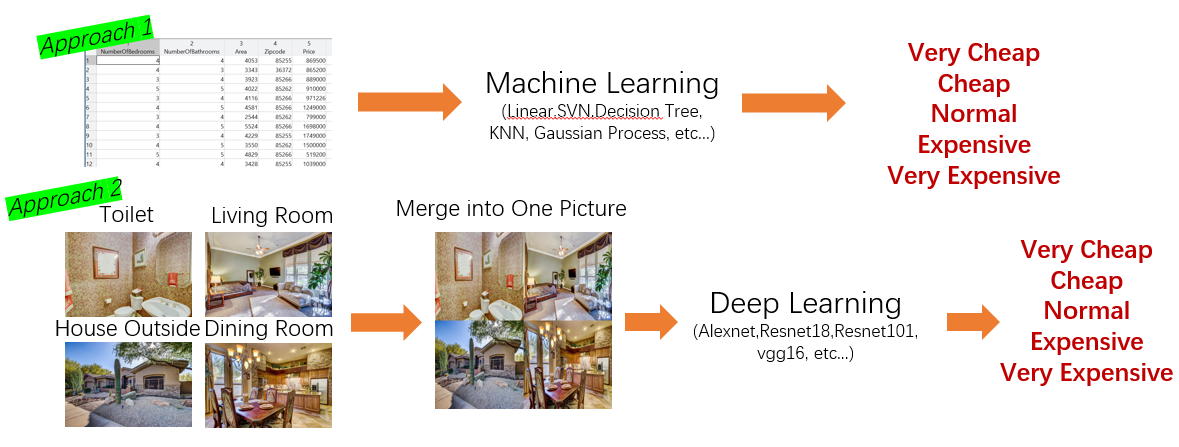

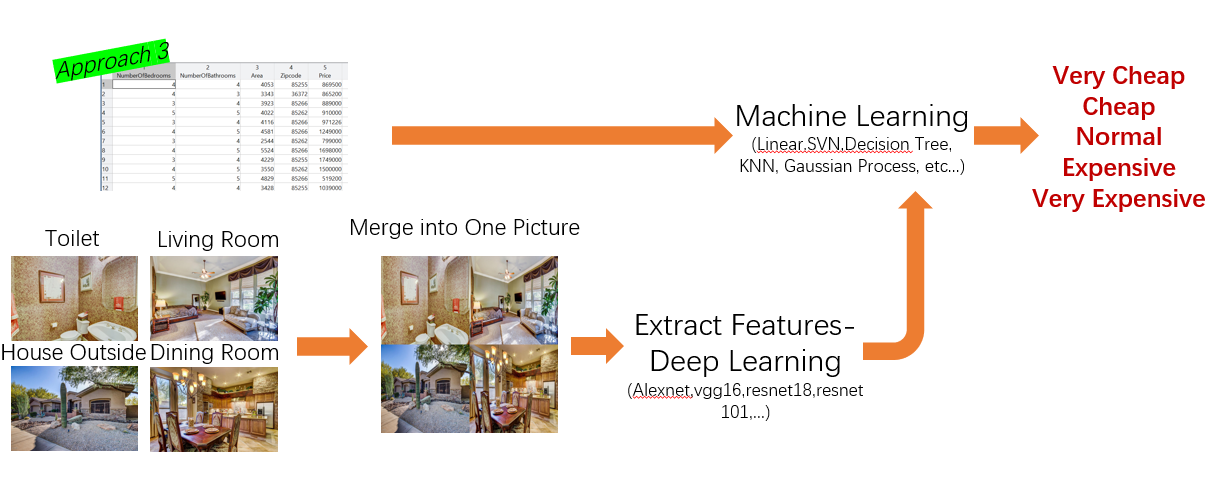

clear all
clc

%Assign same randoness
rng(10)

## Activate Parallel Computing Toolbox

if isempty(gcp('nocreate'))
parpool;
end

## Construct the datastore with Label

Here, we are going to assign label to our merged image. Based on the price in the text file, we are going to divide them equally into 5 categories : ***"Very Cheap", "Cheap", "Normal", "Expensive", "Very Expensive"***

Data = importfile("Houses-dataset-master\Houses Dataset\HousesInfo.txt");
parfor i=1:1:height(Data)
ImageName(i)=sprintf("Dataset%4i.png",i);
end
%Add ImageName to the Data, so it can represent the data
Data.ImageName = ImageName';

%Change the datatype
Data.Price=double(Data.Price);
Data.Zipcode = categorical(Data.Zipcode);

%Change the datatype of Price from String to Double
head(Data)

ans = 8×6 table
    NumberOfBedrooms    NumberOfBathrooms    Area    Zipcode      Price           ImageName    
    ________________    _________________    ____    _______    __________    _________________
           4                    4            4053     85255      8.695e+05    "Dataset   1.png"
           4                    3            3343     36372      8.652e+05    "Dataset   2.png"
           3                    4            3923     85266       8.89e+05    "Dataset   3.png"
           5                    5            4022     85262        9.1e+05    "Dataset   4.png"
           3                    4            4116     85266     9.7123e+05    "Dataset   5.png"
           4                    5            4581     85266      1.249e+06    "Dataset   6.png"
           3

%Now sort the table with price (lowest to highest)
Data = sortrows(Data,"Price");

%Then label it equally with "Very Cheap" "Cheap" "Normal" "Expensive" "Very
%Expensive"
NumberOfImage = height(Data);
Label(1:NumberOfImage/5) = "Very Cheap";
Label(NumberOfImage/5+1:NumberOfImage/5*2) = "Cheap";
Label(NumberOfImage/5*2+1:NumberOfImage/5*3) = "Normal";
Label(NumberOfImage/5*3+1:NumberOfImage/5*4) = "Expensive";
Label(NumberOfImage/5*4+1:NumberOfImage/5*5) = "Super Expensive";

%Add the label to Table
Data.Label = categorical(Label');

%Sort the table by Image_Name
Data = sortrows(Data,"ImageName");

%Preview the Table
Data

Data = 535×7 table
    NumberOfBedrooms    NumberOfBathrooms    Area    Zipcode      Price           ImageName             Label     
    ________________    _________________    ____    _______    __________    _________________    _______________
           4                    4            4053     85255      8.695e+05    "Dataset   1.png"    Super Expensive
           4                    3            3343     36372      8.652e+05    "Dataset   2.png"    Super Expensive
           3                    4            3923     85266       8.89e+05    "Dataset   3.png"    Super Expensive
           5                    5            4022     85262        9.1e+05    "Dataset   4.png"    Super Expensive
           3                    4            4116    

## Approach 1 Machine Learning

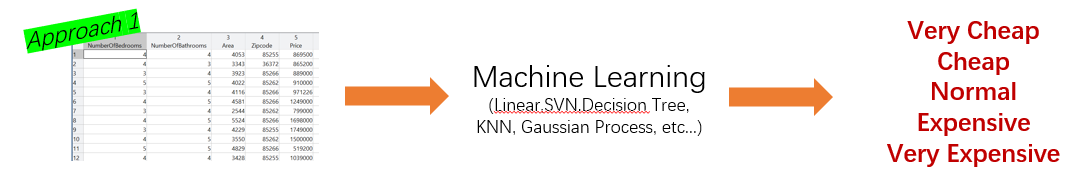

Partition the train data and test data

c = cvpartition(Data.Label,'holdout',0.3)

c = Hold-out cross validation partition
   NumObservations: 535
       NumTestSets: 1
         TrainSize: 375
          TestSize: 160

Training_Data_1 = Data(c.training,:);
Testing_Data_1 = Data(c.test,:);

Open classification learner apps to train the data, remember to untick ImageName as it is not a predictor. Price is the result, it should not be our pretictor as well

classificationLearner;

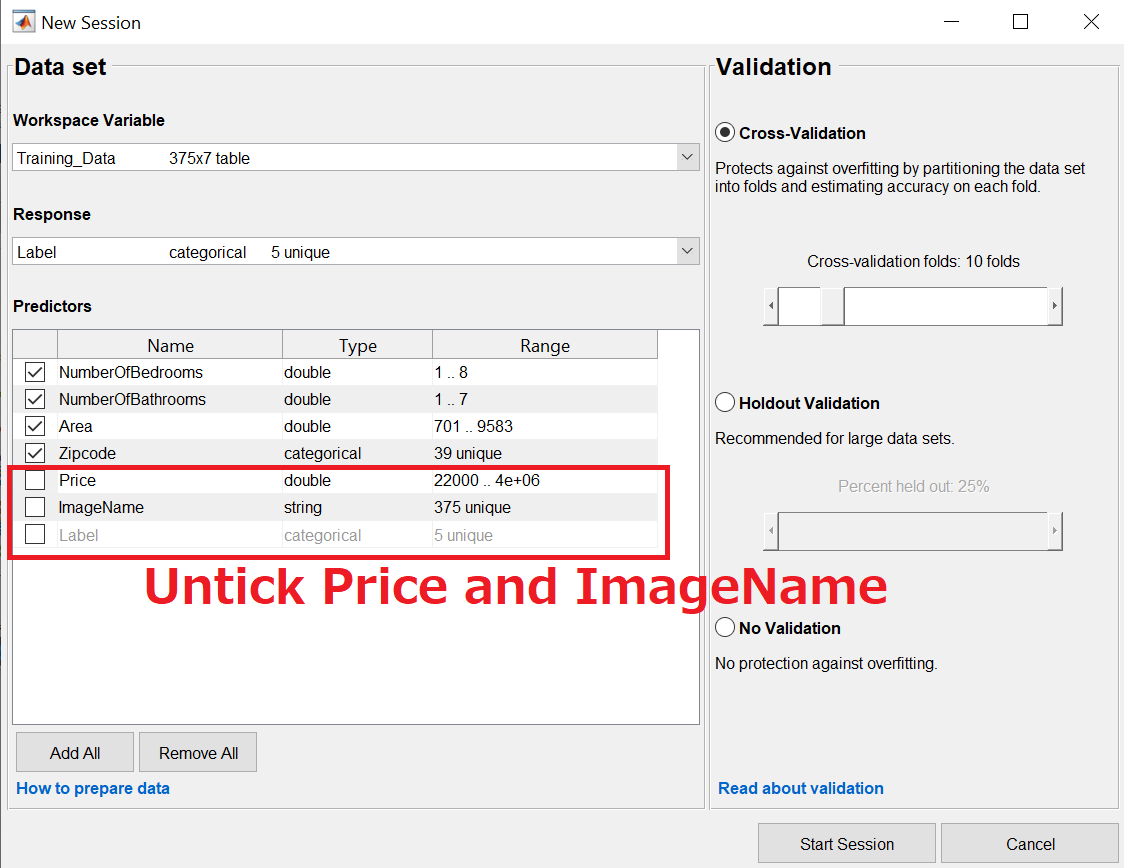

After training, you may export the best model. I have trained the model, you may load the model and justify the accuracy. 

I have save the model in classificationmachinelearning.mat

load classiciationmachinelearning.mat
classiciationmachinelearning

classiciationmachinelearning = struct with fields:
                predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
         RequiredVariables: {'Area'  'NumberOfBathrooms'  'NumberOfBedrooms'  'Zipcode'}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationBaggedEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2019a.'
              HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'

## Justify the accuracy with testing dataset

YPred = classiciationmachinelearning.predictFcn(Testing_Data_1);
accuracy = mean(YPred == Testing_Data_1.Label)

accuracy = 0.8313

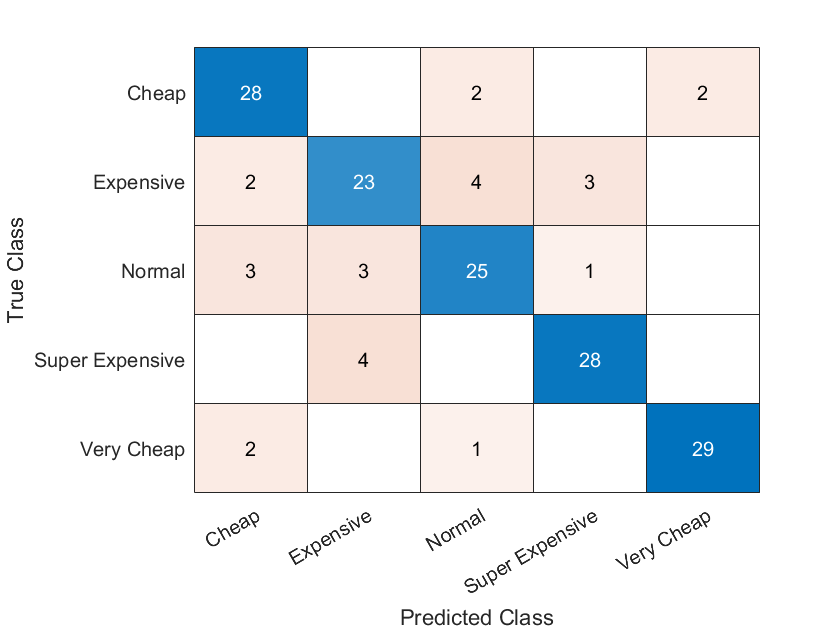


figure
cm = confusionchart(Testing_Data_1.Label,YPred);

## Approach 2 Deep Learning

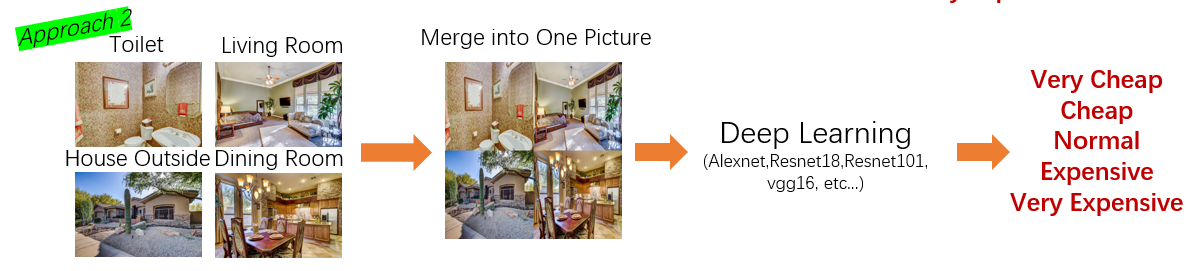

Create the Image Datastore with Label, Split the Data to Train Data and Validation Data

imds = imageDatastore("NewImage","Labels",Data.Label);
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

### Load the Network

net = resnet18;

### Replace Final Layers

The convolutional layers of the network extract image features that the last learnable layer and the final classification layer use to classify the input image. These two layers, `'loss3-classifier'` and `'output'` in most of pretrained neural network, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set.

if isa(net,'SeriesNetwork') 
     lgraph = layerGraph(net.Layers); 
else
    lgraph = layerGraph(net);
end
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
numClasses = numel(categories(Data.Label));
if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end
lgraph= replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);


### Train Network

Use an augmented image datastore to automatically resize the training images so that it fulfill the criteria of input layer of each of pretrained neural network. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation);

### Specify the training options

You might lower down the MiniBatchSize and MaxEpochs to accelerate the training and better handle of the memory.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    "ValidationData",augimdsValidation,...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'ExecutionEnvironment',"gpu",...
    'Plots','training-progress');

By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

### Train the Deep Learning Networks 

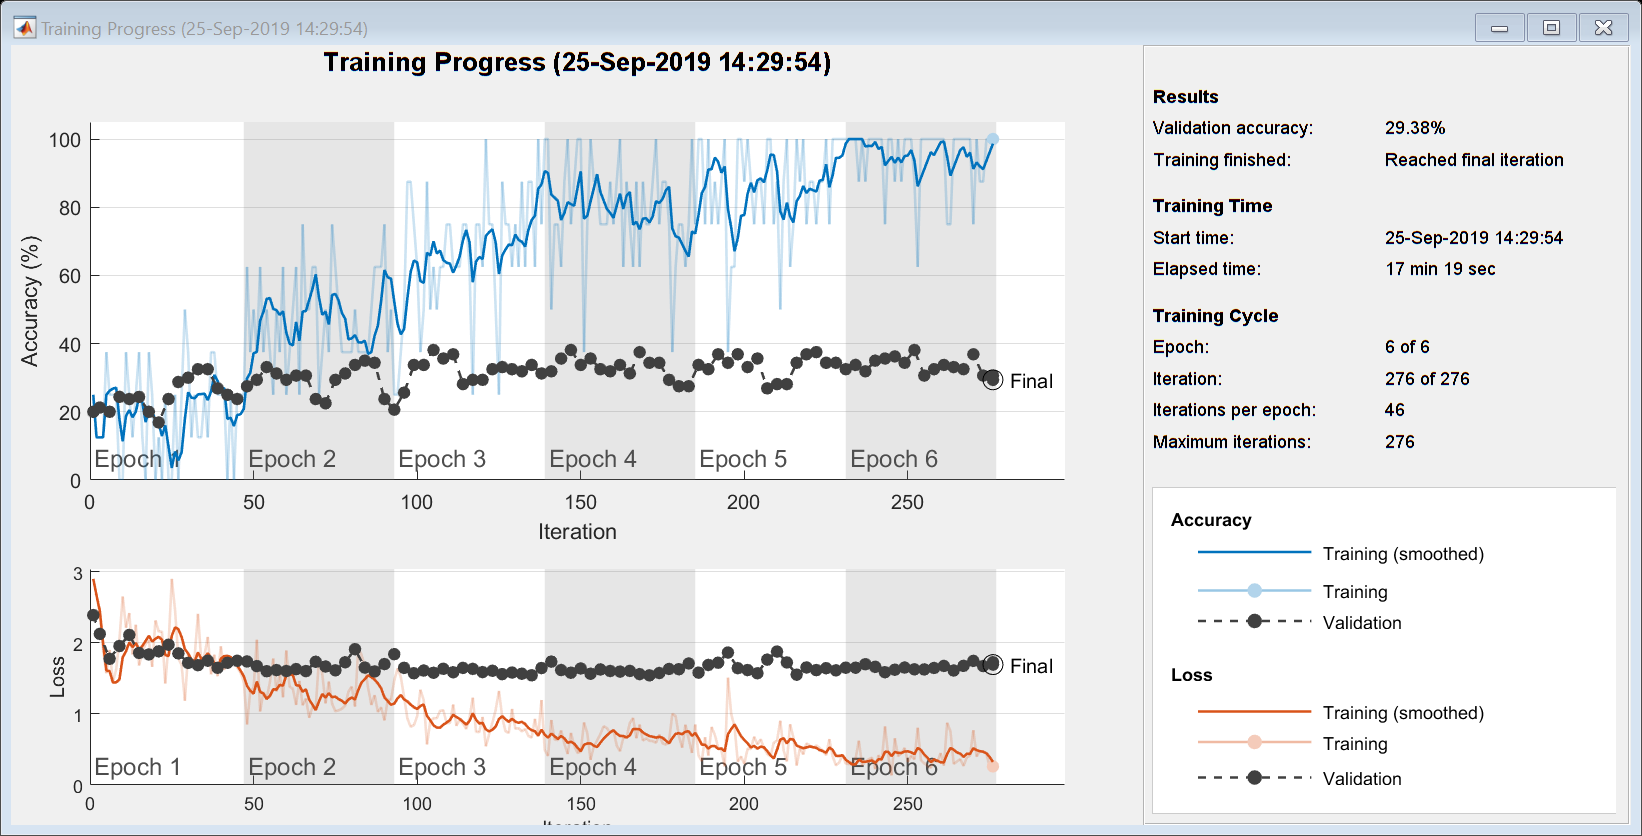

reply = questdlg('Do you want train your deep learning network?It will spend few minutes. You may load the trained deep learning network','Deep Learning Classification','Train','Load','Load');
if strcmp(reply,'Train')==1
    netTransfer = trainNetwork(augimdsTrain,lgraph,options);
else
    load classificationdeeplearning.mat
end

## Classify Validation Images & Calculate the Accuracy using Validation Image

Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(netTransfer,augimdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.2938

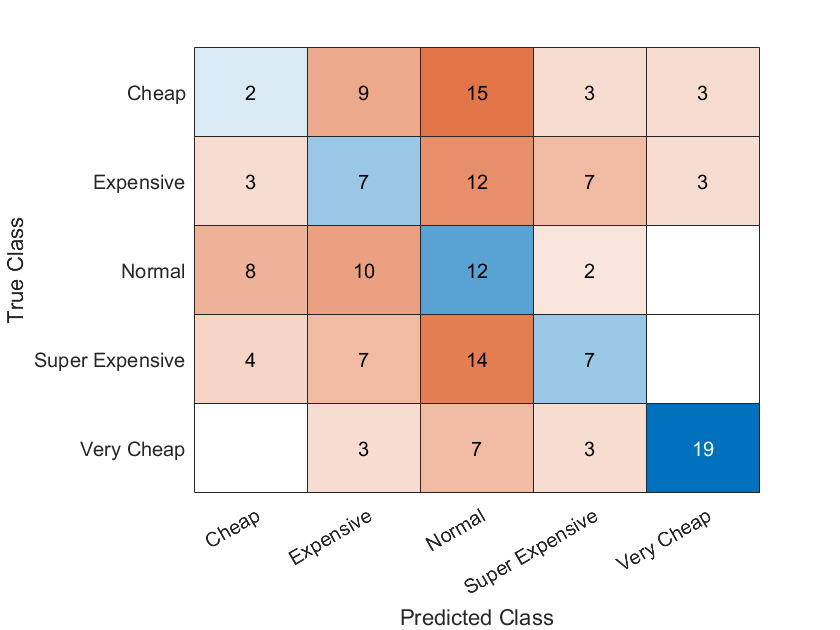



figure
cm = confusionchart(YValidation,YPred);

## Approach 3 Mahine Learning + Deep Learning

### Extract the Features from Deep Learning

layer = 'pool5';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featureValidation = activations(net,augimdsValidation,layer,'OutputAs','rows');

Assign Label to New Variable

YTrain = imdsTrain.Labels;
YValidation = imdsValidation.Labels;

### Assign all  the predictors into table for Machine Learning

table_o= array2table([featuresTrain;featureValidation]);
table_o.YTrain = [YTrain;YValidation];
table_o.FileNames = [augimdsTrain.Files(:);augimdsValidation.Files(:)];

table_o= sortrows(table_o,"FileNames");
table_o = [table_o Data(:,1:5)];

Visualize the table

table_o

table_o = 535×519 table
      Var1       Var2       Var3       Var4        Var5       Var6        Var7       Var8       Var9       Var10      Var11       Var12      Var13       Var14      Var15       Var16        Var17      Var18      Var19      Var20       Var21       Var22      Var23       Var24      Var25       Var26      Var27      Var28       Var29       Var30       Var31      Var32      Var33      Var34       

### Partition the train data and test data

c = cvpartition(table_o.YTrain,'holdout',0.3)

c = Hold-out cross validation partition
   NumObservations: 535
       NumTestSets: 1
         TrainSize: 375
          TestSize: 160

Training_Data_2 = table_o(c.training,:);
Testing_Data_2 = table_o(c.test,:);

### Train Machine Learning Model

Open classification learner apps to train the data, remember to untick ImageName as it is not a predictor. Price is the result, it should not be our pretictor as well

classificationLearner;

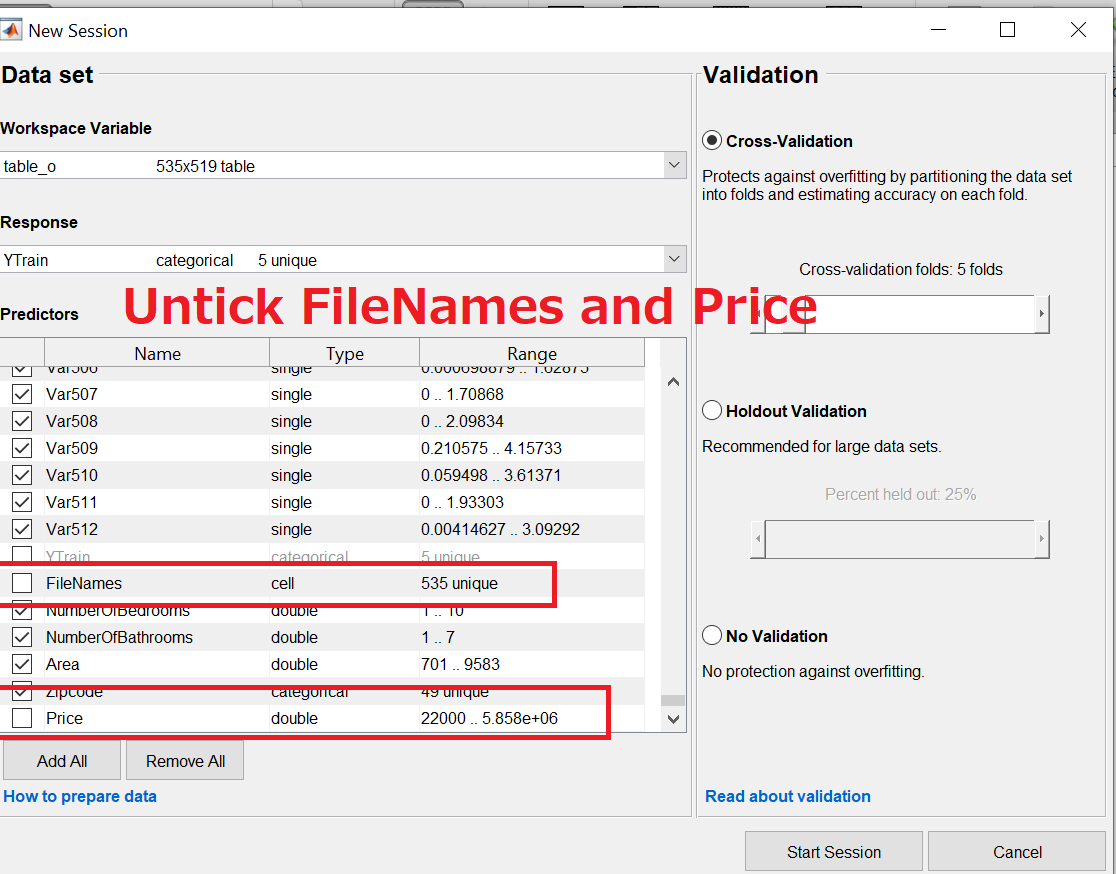

After training, you may export the best model. I have trained the model, you may load the model and justify the accuracy. 

I have save the model in classificationmachinelearning.mat

load classiciationmachinelearningdeeplearning.mat
classiciationmachinelearningdeeplearning

classiciationmachinelearningdeeplearning = struct with fields:
                predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
         RequiredVariables: {1×516 cell}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2019a.'
              HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'

## Justify the accuracy with testing dataset

YPred = classiciationmachinelearningdeeplearning.predictFcn(Testing_Data_2);
accuracy = mean(YPred == Testing_Data_2.YTrain)

accuracy = 0.7188

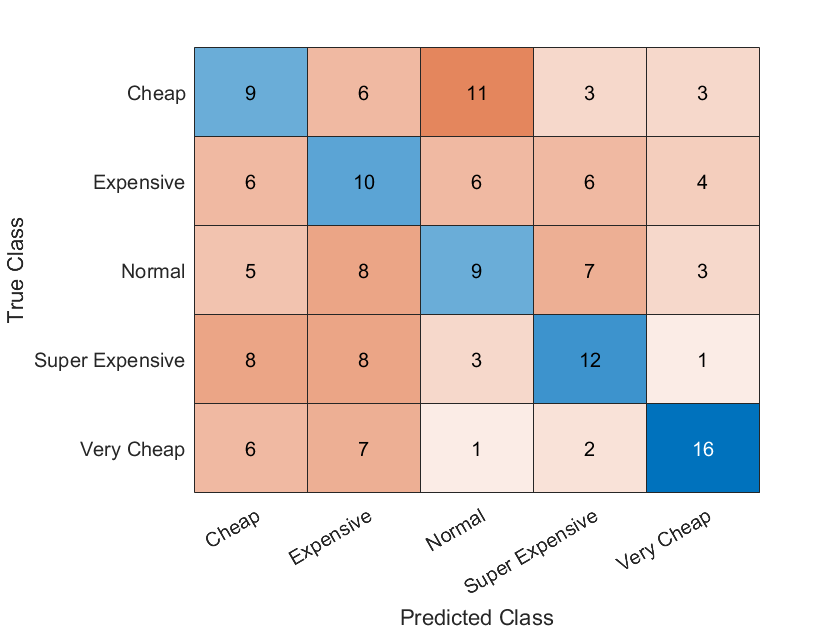


figure
cm = confusionchart(Testing_Data.YTrain,YPred);

## Compare the accuracy of 3 Approaches

YPred1 = classiciationmachinelearning.predictFcn(Data);
YPred2 = classify(netTransfer,augimdsValidation);
YPred3 = classiciationmachinelearningdeeplearning.predictFcn(table_o);
YValidation = imdsValidation.Labels;
accuracy1 = mean(YPred1 == Data.Label);
accuracy2 = mean(YPred2 == YValidation);
accuracy3 = mean(YPred3 == table_o.YTrain);
compare_table=table(accuracy1,accuracy2,accuracy3);
compare_table.Properties.VariableNames(1)="Machine_Learning";
compare_table.Properties.VariableNames(2)="Deep_Learning";
compare_table.Properties.VariableNames(3)="Deep_Learning_Machine_Learning"

compare_table = 1×3 table
    Machine_Learning    Deep_Learning    Deep_Learning_Machine_Learning
    ________________    _____________    ______________________________
         0.8486            0.29375                  0.74393            

Although the approaches here might not optimised, but does deep learning neccessary? Sometimes, machine learning is working better.